**This file loads data on population size of various European economies from 2003 to 2025 (yearly frequency). **Data is taken from Eurostat and is analysed using various regression models:

load demodata 
demodata.Properties.VariableNames(1)={'Countries'}

demodata = 12×14 table
     Countries         x03           x04           x05           x06           x07           x08           x09           x10           x11           x12           x13           x14           x15    
    ____________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________

    {'TIME'    }          2003          2004          2005          2006          2007          2008  

years=2003:1:2015; % x-axis timeline
nations=demodata.Countries;
i=[1,2,5,7,10] % rows to remove from table

i =      1     2     5     7    10


nations(i)=[]

nations = 7×1 cell array
    {'Belgium' }
    {'Bulgaria'}
    {'Denmark' }
    {'Estonia' }
    {'Ireland' }
    {'Spain'   }
    {'France'  }


data=demodata{:,2:end}; % table2array
data(i,:)=[]; % demographic data needed 
data=data./1000000 % demodata now in millions

data =    10.3558   10.3964   10.4459   10.5114   10.5845   10.6669   10.7531   10.8399   11.0006   11.0759   11.1380   11.1808   11.2373
    7.8055    7.7451    7.6886    7.6294    7.5727    7.5180    7.4671    7.4218    7.3694    7.3272    7.2846    7.2457    7.2022
    5.3835    5.3976    5.4114    5.4275    5.4471    5.4758    5.5115    5.5347    5.5606    5.5805    5.6026    5.6272    5.6597
    1.3752    1.3662    1.3588    1.3507    1.3429    1.3384    1.3357    1.3333    1.3297    1.3252    1.3202    1.3158    1.3149
    3.9642    4.0289    4.1117    4.2082    4.3401    4.4578    4.5213    4.5494    4.5709    4.5893    4.6098    4.6379    4.6776
   41.8278   42.5475   43.2963   44.0100   44.7847   45.6689   46.2393   46.4866   46.6672   46.8182   46.7279   46.5122   46.4496
   61.8641   62.2922   62.7729   63.2296   63.6451   64.0072   64.3502   64.6589   64.9787   65.2770   65.6004   66.1660   66.4582


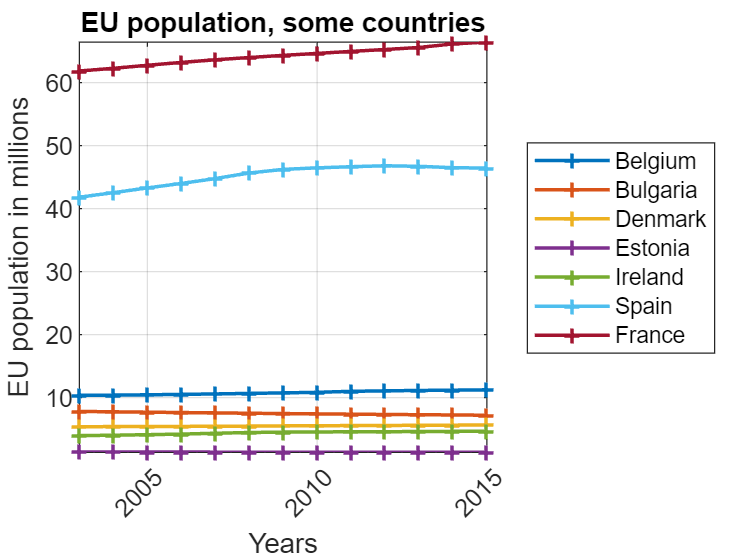

plot(years,data,'+-','linewidth',1.4)
grid on
axis tight 
xlabel('Years')
xtickangle(45)
ylabel('EU population in millions')
legend(nations,'Location','eastoutside')
title('EU population, some countries')

**This code section **uses a **custom function for polynomial fitting **and **scatterplot, **as well as **fits a linear regression model to the average EU population data **(average based on the chosen countries):

**We want to predict European population size for the next 10 years based on the data avaliable: **using the linear model for prediction:

disp('Drop down menu for each nation, and its scatterplot:')

Drop down menu for each nation, and its scatterplot:


nation="Estonia"

nation = "Estonia"

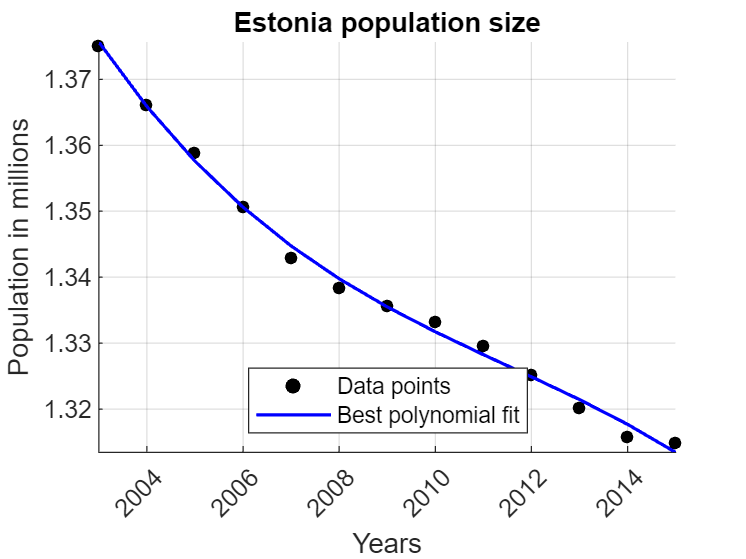

polynom =    -0.0020    0.0038   -0.0155    1.3355


polynom=polymodel(nation)

meandata=mean(data,1)'; % column of mean data
years=years'; % column regressor vector
LinearModel=fitlm(years,meandata) % fitting a linear simple model

LinearModel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)    -235.57        18.708    -12.592    7.0821e-08
    x1             0.12714     0.0093123     13.653     3.055e-08


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.126
R-squared: 0.944,  Adjusted R-Squared: 0.939
F-statistic vs. constant model: 186, p-value = 3.06e-08

disp('Pvalues are small, a statistically significant regression against time')

Pvalues are small, a statistically significant regression against time


future_years=[016:1:2025]' % future 10 years

future_years =         2016
        2017
        2018
        2019
        2020
        2021
        2022
        2023
        2024
        2025


meanPopulation_future=predict(LinearModel,future_years)

meanPopulation_future =    20.7482
   20.8753
   21.0025
   21.1296
   21.2568
   21.3839
   21.5110
   21.6382
   21.7653
   21.8925


meandata =    18.9395
   19.1106
   19.2979
   19.4810
   19.6739
   19.8761
   20.0255
   20.1178
   20.2110
   20.2848


**Interpolation for average population in EU in the middle of 2008:**

year_interpolate=2008.5 % 2008 year and 6 months

year_interpolate = 2.0085e+03

population_interpolate=interp1(years,meandata,year_interpolate,'linear')

population_interpolate = 19.9508

**Custom function: **builds a scatterplot of nation data and fits a polynomial of degree n:

function polynom=polymodel(nation)
load demodata 
demodata.Properties.VariableNames(1)={'Countries'};
years=2003:1:2015; % x-axis timeline
nations=demodata.Countries;
i=[1,2,5,7,10];% rows to remove from table
nations(i)=[];
data=demodata{:,2:end}; % table2array
data(i,:)=[]; % demographic data needed 
data=data./1000000; % demodata now in millions
log_nation=strcmp(nation,nations);
index_nation=find(log_nation);
nationData=data(index_nation,:);
scatter(years,nationData,25,'k','filled')
grid on
axis tight
xlabel('Years')
xtickangle(45)
ylabel('Population in millions')
title(nation+' population size')
n=3; % degree of polynomial fit
[polynom,~,scales]=polyfit(years,nationData,n);
fittedLine=polyval(polynom,years,[],scales);
hold on
plot(years,fittedLine,'b','linewidth',1.3)
legend('Data points','Best polynomial fit','Location','south')
hold off
end 